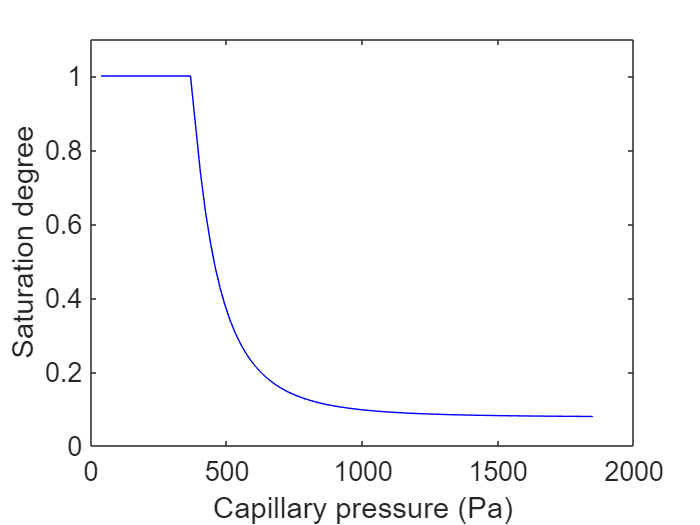

% Material parameters
lambda = 3.86;
pb     = 369.73;
Slr    = 0.078;
Sgr    = 0.0;
% Capillary pressure
pc = linspace(0.1*pb,5*pb,100);
% Effective saturation degree
Se = (pc./pb).^(-lambda);
% Saturation degre
Sl = Se * (1.0 - Slr - Sgr) + Slr;
Sl = max(min(Sl, 1.0 - Sgr - eps), Slr + eps);
plot(pc,Sl,'b')
xlabel('Capillary pressure (Pa)');
ylabel('Saturation degree');
ylim([0.0 1.1])
set(gca,'FontSize',16)

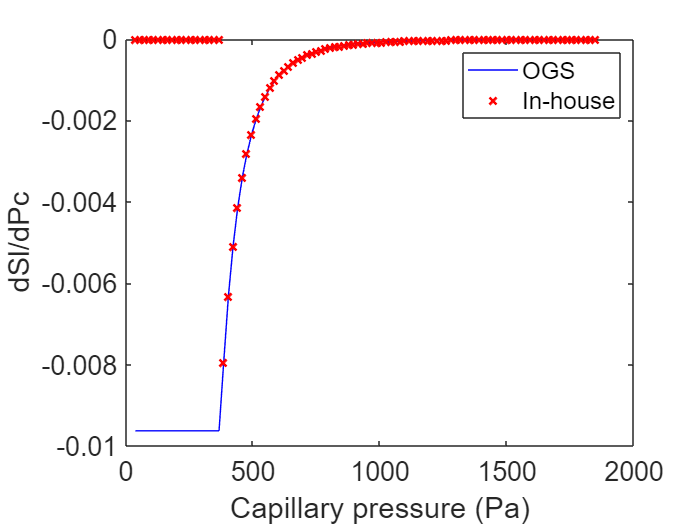

% Derivative of the saturation degree wrt to the capillary pressure
dPcdSl = (pb ./ (lambda .* (Slr - Sl))) .* ((Sl - Slr)./(1.0 - Sgr - Slr)) .^ (-1.0/lambda);
dSldPc = 1.0 ./ dPcdSl;
plot(pc,dSldPc,'b')
hold on
% Direct computation
dSedPc = -(lambda / pb) * (pc ./ pb) .^ (-lambda - 1);
dSldPc = (1.0 - Slr - Sgr) * dSedPc;
dSldPc(pc < pb) = 0.0;
plot(pc,dSldPc,'xr','LineWidth',1.5)
xlabel('Capillary pressure (Pa)');
ylabel('dSl/dPc');
set(gca,'FontSize',16)
legend('OGS','In-house')